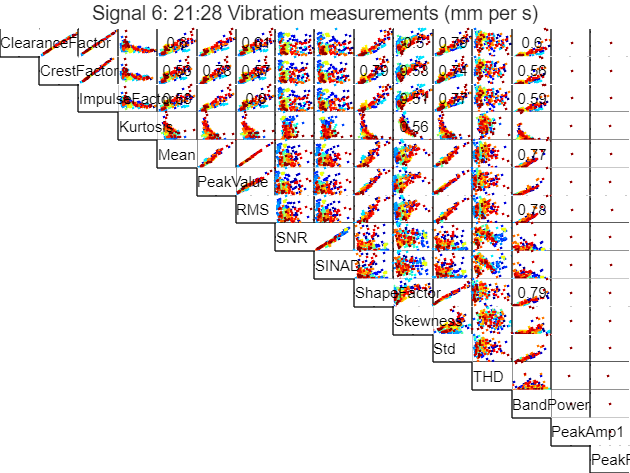

Features = DFD_FeatureTable_TimeDomain;
FeatureNames = FeatureNames_Combined;
lowerR2 = 0.3;
upperR2 = 0.8;
selectedSignal = 6; % 21:28 Vibration measurements (mm per s)
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, selectedSignal, FeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  1.00  1.00  0.22  0.60  0.82  0.61  0.02  0.01  0.84  0.50  0.79  0.04  0.60   NaN   NaN
0.00  0.00  1.00  0.21  0.56  0.78  0.57  0.02  0.01  0.79  0.53  0.74  0.04  0.56   NaN   NaN
0.00  0.00  0.00  0.22  0.58  0.80  0.60  0.02  0.01  0.82  0.51  0.77  0.04  0.59   NaN   NaN
0.00  0.00  0.00  0.00  0.06  0.12  0.06  0.01  0.01  0.21  0.56  0.17  0.02  0.10   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.93  1.00  0.04  0.03  0.80  0.06  0.91  0.02  0.77   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.94  0.03  0.02  0.92  0.19  0.97  0.03  0.82   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.03  0.82  0.06  0.92  0.02  0.78   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.96  0.02  0.00  0.02  0.00  0.02   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.00  0.01  0.00  0.01   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.25  0.97  0.01  0.79   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2);
disp(selectedFeatureArray);

     1     5     7    11    12    14



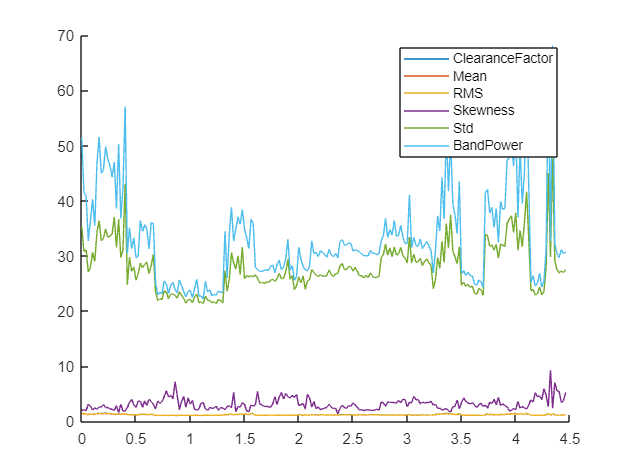

n = size(selectedFeatureData{1}, 1);
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for signalIndex = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{signalIndex});
    txtTemp = char(FeatureNames(selectedFeatureArray(signalIndex)));
    leg{signalIndex} = char(txtTemp);
end
title(sensorNames(selectedSignal));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

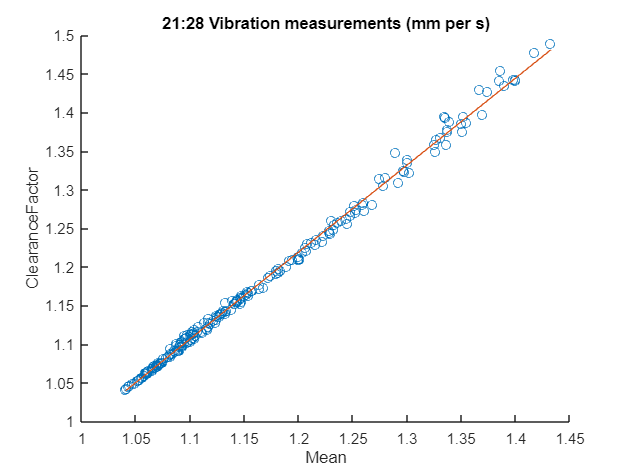

FIT = 94.37

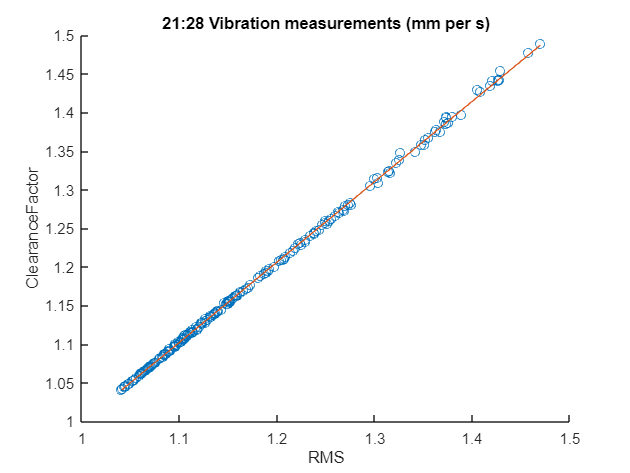

FIT = 98.03

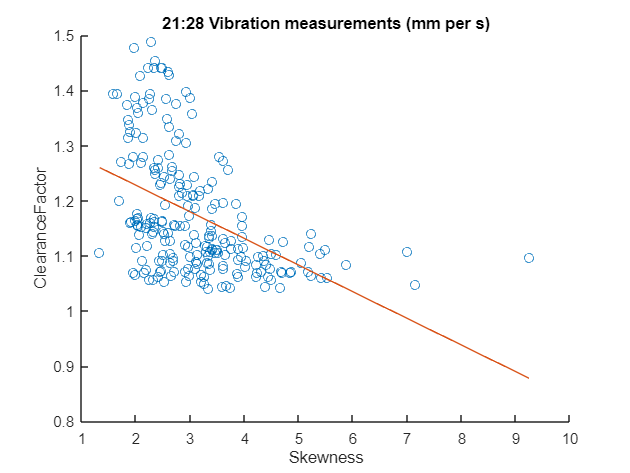

FIT = 11.49

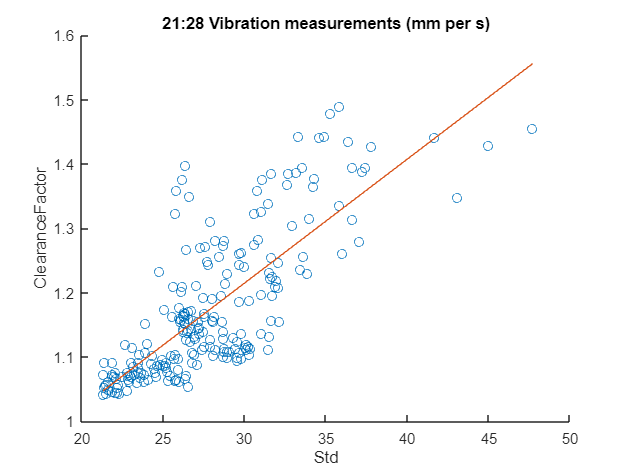

FIT = 36.48

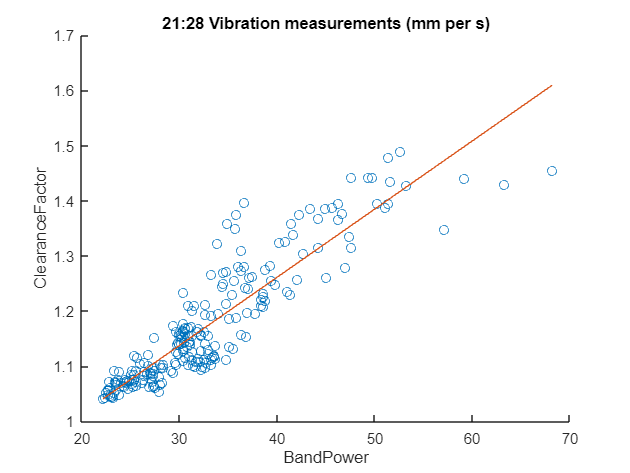

FIT = 57.21

for index = 1 : numOfSelectedFeatures
    if index ~= selectedFeature
        fnPlotModel(selectedFeatureData{selectedFeature}, selectedFeatureData{index}, sensorNames(selectedSignal), FeatureNames(selectedFeatureArray(selectedFeature)), FeatureNames(selectedFeatureArray(index)));
    end
end

1 2 3

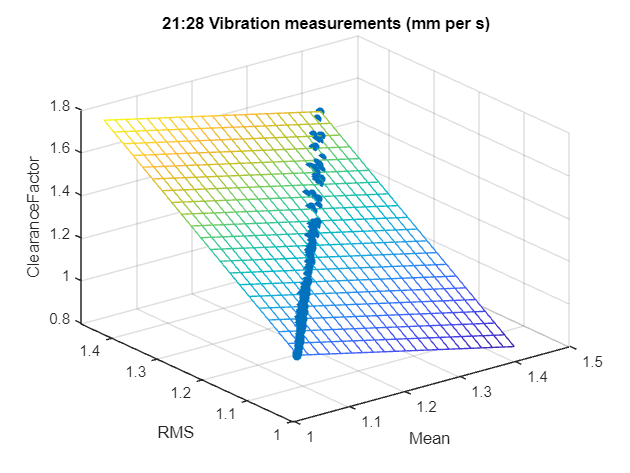

FIT = 99.757368

1 2 4

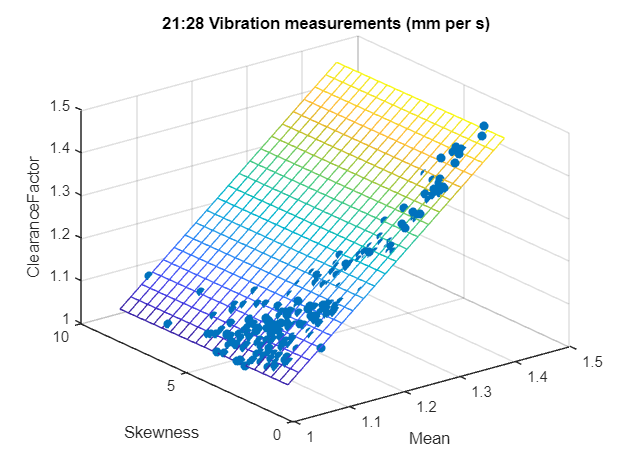

FIT = 94.382558

1 2 5

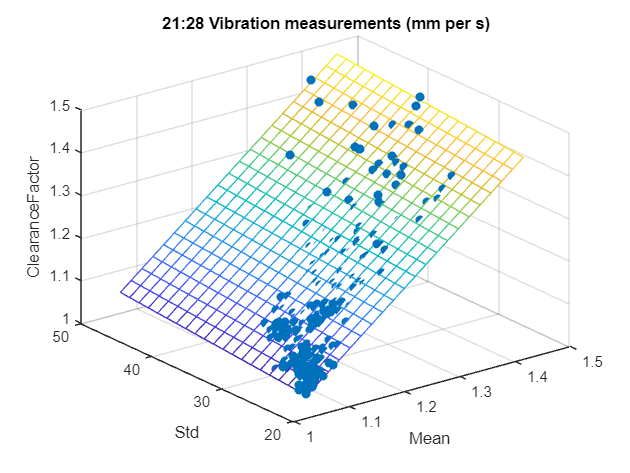

FIT = 96.156972

1 2 6

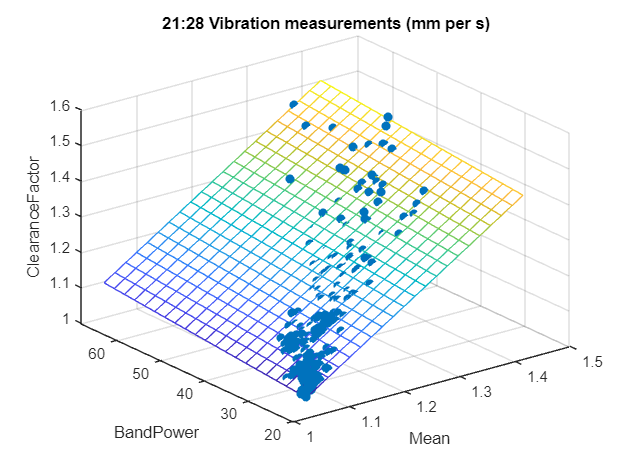

FIT = 96.614039

1 3 4

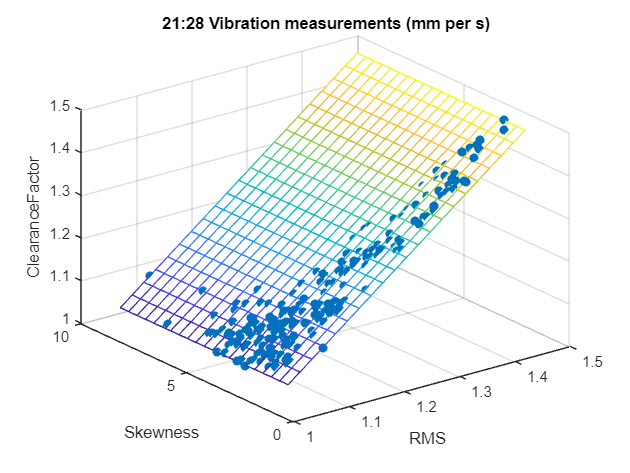

FIT = 98.033832

1 3 5

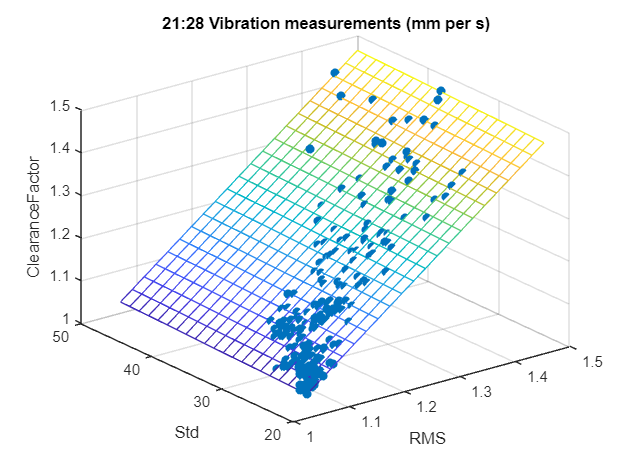

FIT = 98.668591

1 3 6

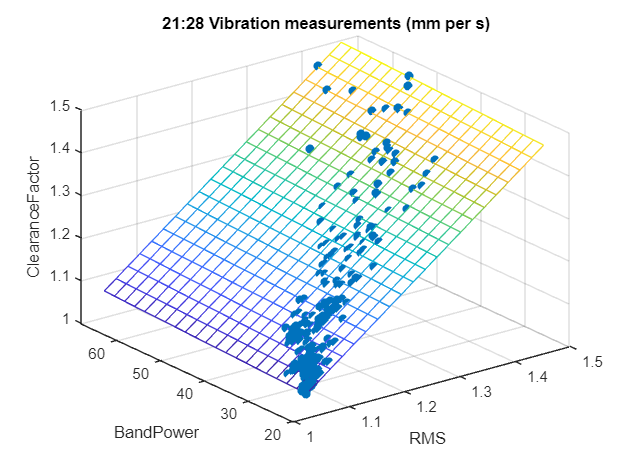

FIT = 98.815131

1 4 5

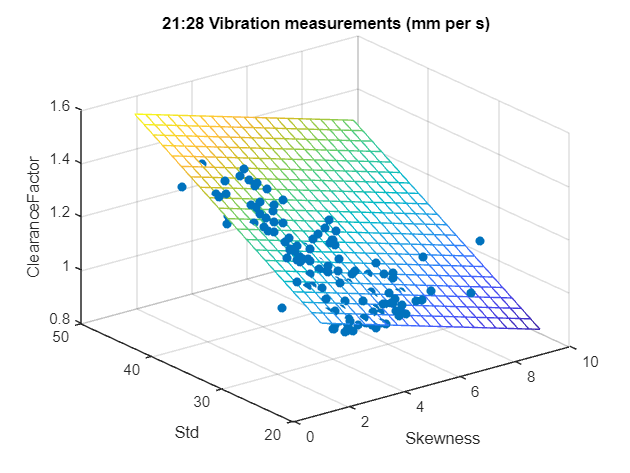

FIT = 43.511737

1 4 6

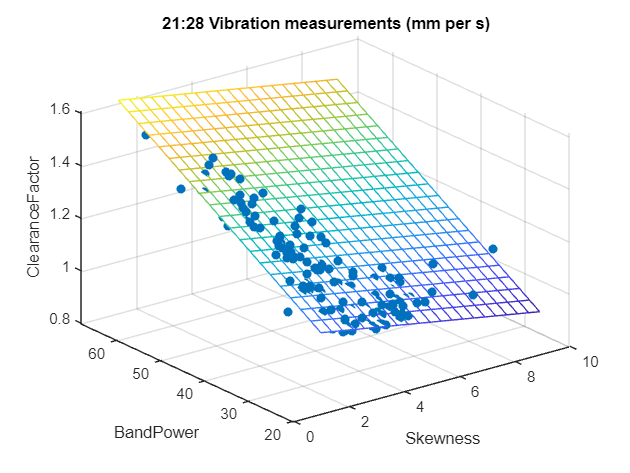

FIT = 60.613356

1 5 6

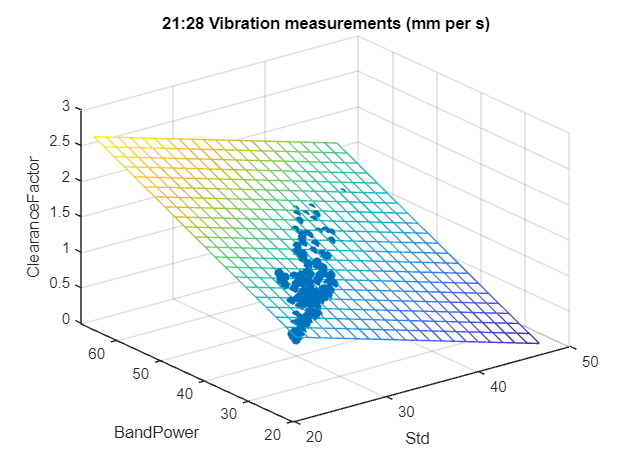

FIT = 83.689870

for index1 = 2 : numOfSelectedFeatures
    for index2 = index1+1 : numOfSelectedFeatures
        fprintf("%i %i %i", 1, index1, index2);
        Y_est = fnPlotModel3D( ...
            selectedFeatureData{1}, ...
            selectedFeatureData{index1}, ...
            selectedFeatureData{index2}, ...
            sensorNames(selectedSignal), ...
            FeatureNames(selectedFeatureArray(1)), ...
            FeatureNames(selectedFeatureArray(index1)), ...
            FeatureNames(selectedFeatureArray(index2)));
    end
end